%question_3

%import data
dataset = importdata('/Users/ethanvictormonkhouse/midterm2021.php');
dataset = dataset(1:100,:)

dataset =      1     2     1
     1     2     3
     0     0     1
     0     0     2
     1     2     0
     1     3     0
     0     1     0
     1     2     3
     0     1     3
     1     2     3


[numberOfRows,numberOfColumns]=size(dataset);
fprintf("The dataset contains %d rows, and %d columns. \n", numberOfRows, numberOfColumns);

The dataset contains 100 rows, and 3 columns. 


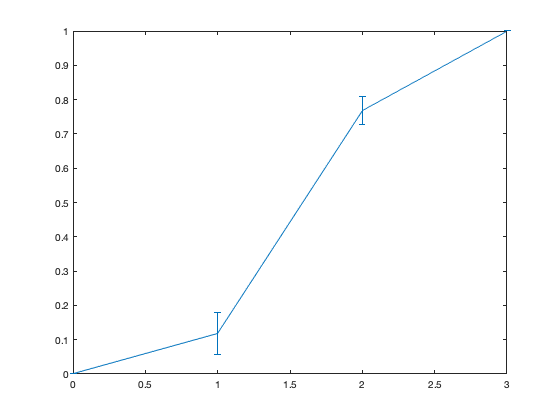


%part_a
z_values = (min(dataset(:,2)):max(dataset(:,2)));
probability_2_true = zeros(max(dataset(:,2))+1,1); %define array
probability_2_1_true = zeros(max(dataset(:,2))+1,1); %define array
for i = z_values %calculate quantities for z
    probability_2_1_true(i+1) = sum(dataset(:,2) == i & dataset(:,1) == 1)/numberOfRows; %probability of column1=1 and column2=z
    probability_2_true(i+1) = sum(dataset(:,2) == i )/numberOfRows; %probability of column2=z
end

probability_zi2_given_zi1 = probability_2_1_true./probability_2_true; %probability of column1=1 and column2=z occurring given column1=1

%calculate variance for each z value
variance = zeros(max(dataset(:,2))+1,1); %define array

for i = z_values %iterate through all quantites
    totalSum = 0; %reset totalSum for next quantity
    for j = 1:numberOfRows %iterate through every basket
        if (dataset(j,2) == i) && (dataset(j,1) == 1) %if column2 = z and column1 = 1
            totalSum = totalSum + (1 - probability_zi2_given_zi1(i+1,1))^2; %calculate total sum of expected values minus the expected sample mean, squared
        end
    end
    variance(i+1) = totalSum/numberOfRows; %calculate variance, which is the totalSum divided by the population
end

%calculate variance and confidence intervals
standardError = zeros(max(dataset(:,2))+1,1); %define array
marginError = zeros(max(dataset(:,2))+1,1); %define array
CLTLowerBound = zeros(max(dataset(:,2))+1,1); %define array
CLTUpperBound = zeros(max(dataset(:,2))+1,1); %define array
ChebyshevLowerBound = zeros(max(dataset(:,2))+1,1); %define array
ChebyshevUpperBound = zeros(max(dataset(:,2))+1,1); %define array

for i = z_values %iterate through all quantities
    standardError(i+1) = sqrt(variance(i+1))/sqrt(sum(dataset(:,2) == i)); %SE=standard deviation/sqrt(n)
    marginError(i+1) = sqrt(variance(i+1))/(sqrt(sum(dataset(:,2) == i)*0.05)); %ME.95=standard deviation/sqrt(0.05*n)
    
    CLTLowerBound(i+1) = probability_zi2_given_zi1(i+1) - 2*(standardError(i+1)); %CLT mean - 2(SE)
    CLTUpperBound(i+1) = probability_zi2_given_zi1(i+1) + 2*(standardError(i+1)); %CLT mean + 2(SE)
    
    ChebyshevLowerBound(i+1) = probability_zi2_given_zi1(i+1) - marginError(i+1); %Chebyshev mean - marginOfError
    ChebyshevUpperBound(i+1) = probability_zi2_given_zi1(i+1) + marginError(i+1); %Chebyshev mean + marginOfError
end

errorbar(z_values, probability_zi2_given_zi1, probability_zi2_given_zi1-CLTLowerBound, CLTUpperBound-probability_zi2_given_zi1); %using CLT method

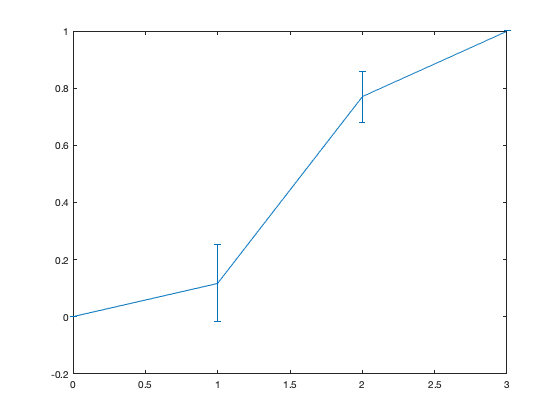

errorbar(z_values, probability_zi2_given_zi1, probability_zi2_given_zi1-ChebyshevLowerBound, ChebyshevUpperBound-probability_zi2_given_zi1); %using Chebyshev method


%import data
dataset = importdata('/Users/ethanvictormonkhouse/midterm2021.php');
[numberOfRows,numberOfColumns]=size(dataset);
fprintf("The dataset contains %d rows, and %d columns. \n", numberOfRows, numberOfColumns);

The dataset contains 1435 rows, and 3 columns. 


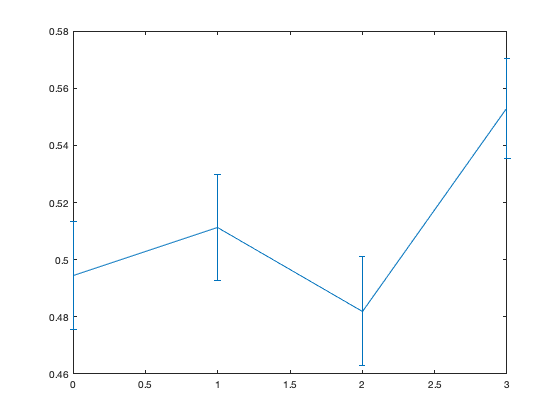


%part_b
z_values = (min(dataset(:,3)):max(dataset(:,3)));
probability_3_true = zeros(max(dataset(:,3))+1,1); %define array
probability_3_1_true = zeros(max(dataset(:,3))+1,1); %define array
for i = z_values %calculate quantities for z
    probability_3_1_true(i+1) = sum(dataset(:,3) == i & dataset(:,1) == 1)/numberOfRows; %probability of column1=1 and column2=z
    probability_3_true(i+1) = sum(dataset(:,3) == i )/numberOfRows; %probability of column2=z
end

probability_zi3_given_zi1 = probability_3_1_true./probability_3_true; %probability of column1=1 and column2=z occurring given column1=1

%calculate variance for each z value
variance = zeros(max(dataset(:,2))+1,1); %define array

for i = z_values %iterate through all quantites
    totalSum = 0; %reset totalSum for next quantity
    for j = 1:numberOfRows %iterate through every basket
        if (dataset(j,3) == i) && (dataset(j,1) == 1) %if column2 = z and column1 = 1
            totalSum = totalSum + (1 - probability_zi3_given_zi1(i+1,1))^2; %calculate total sum of expected values minus the expected sample mean, squared
        end
    end
    variance(i+1) = totalSum/numberOfRows; %calculate variance, which is the totalSum divided by the population
end

%calculate variance and confidence intervals
standardError = zeros(max(dataset(:,3))+1,1); %define array
marginError = zeros(max(dataset(:,3))+1,1); %define array
CLTLowerBound = zeros(max(dataset(:,3))+1,1); %define array
CLTUpperBound = zeros(max(dataset(:,3))+1,1); %define array
ChebyshevLowerBound = zeros(max(dataset(:,3))+1,1); %define array
ChebyshevUpperBound = zeros(max(dataset(:,3))+1,1); %define array

for i = z_values %iterate through all quantities
    standardError(i+1) = sqrt(variance(i+1))/sqrt(sum(dataset(:,3) == i)); %SE=standard deviation/sqrt(n)
    marginError(i+1) = sqrt(variance(i+1))/(sqrt(sum(dataset(:,3) == i)*0.05)); %ME.95=standard deviation/sqrt(0.05*n)
    
    CLTLowerBound(i+1) = probability_zi3_given_zi1(i+1) - 2*(standardError(i+1)); %CLT mean - 2(SE)
    CLTUpperBound(i+1) = probability_zi3_given_zi1(i+1) + 2*(standardError(i+1)); %CLT mean + 2(SE)
    
    ChebyshevLowerBound(i+1) = probability_zi3_given_zi1(i+1) - marginError(i+1); %Chebyshev mean - marginOfError
    ChebyshevUpperBound(i+1) = probability_zi3_given_zi1(i+1) + marginError(i+1); %Chebyshev mean + marginOfError
end

errorbar(z_values, probability_zi3_given_zi1, probability_zi3_given_zi1-CLTLowerBound, CLTUpperBound-probability_zi3_given_zi1); %using CLT method

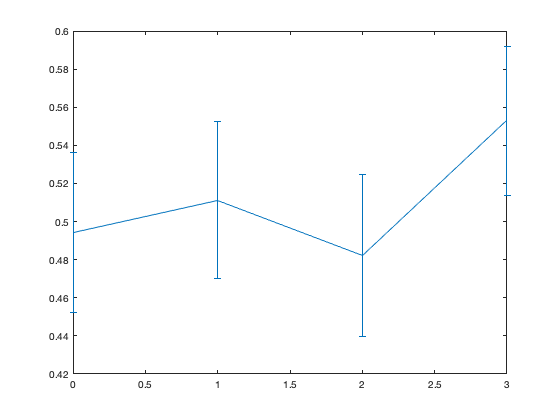

errorbar(z_values, probability_zi3_given_zi1, probability_zi3_given_zi1-ChebyshevLowerBound, ChebyshevUpperBound-probability_zi3_given_zi1); %using Chebyshev method


p1 = zeros(max(dataset(:,3))+1,1); %define array
p3 = zeros(max(dataset(:,3))+1,1); %define array
p13 = zeros(max(dataset(:,3))+1,1); %define array

for i = z_values %calculate quantities for z
    p3(i+1) = sum(dataset(:,3) == i)/numberOfRows; %E[X]
    p1(i+1) = sum(dataset(:,1) == 1)/numberOfRows; %E[Y]
    p13(i+1) = p2(i+1)*p1(i+1); %E[X]E[Y]
end